## Treino para teste PL1

#### 1. Crie os seguintes sinais no workspace do MATLAB, usando um período de amostragem 𝑇𝑎 = 0.01 segundos. 

Ta = 0.01;

#### a) 𝑥(𝑡) = 2 sin(4𝜋𝑡) , 𝑡 ∈ [0; 5] 

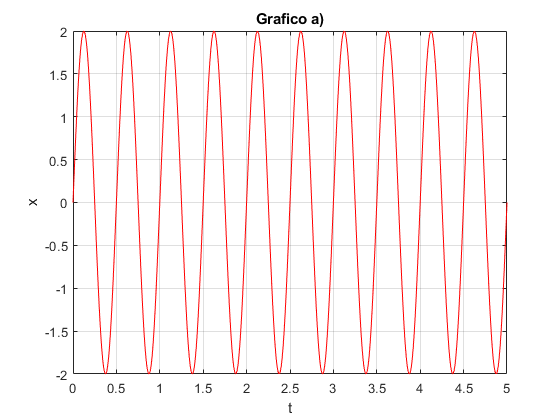

t = (0:Ta:5);
x = 2.*sin(4*pi.*t);
plot(t,x,"r");
xlabel("t");
ylabel("x");
title("Grafico a)");
grid;

#### b) 𝑦(𝑡) = cos(10𝜋𝑡) , 𝑡 ∈ [0; 5] 

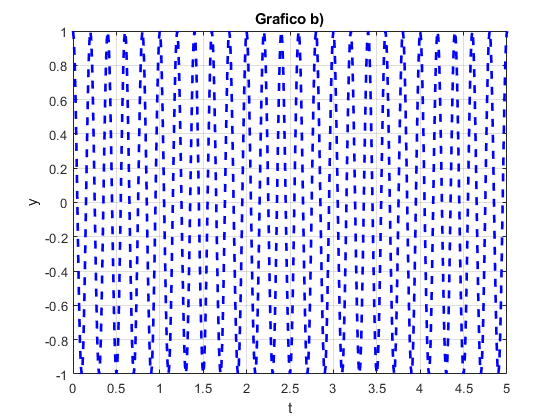

t = (0:Ta:5);
y = cos(10*pi.*t);
plot(t,y,"--b","LineWidth",2.0);
xlabel("t");
ylabel("y");
title("Grafico b)");
grid;

#### c) 𝑧(𝑡) = 𝑥(𝑡)𝑦(𝑡) 

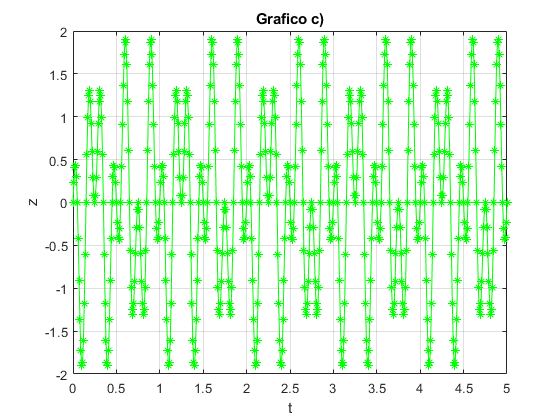

z = x.*y;
plot(t,z,"-*g");
xlabel("t");
ylabel("z");
title("Grafico c)");
grid;

#### d) 𝑤(𝑡) = 3 sin(𝜋𝑡) + 2 sin(6𝜋𝑡) , 𝑡 ∈ [0; 10] 

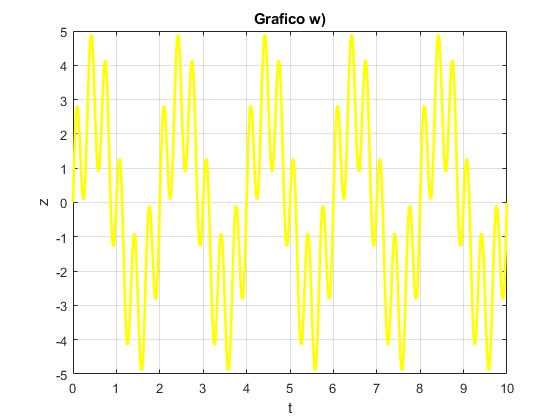

t = (0:Ta:10);
w = 3.*sin(pi.*t) + 2.*sin(6*pi.*t);
plot(t,w,"-y","LineWidth",2.0);
xlabel("t");
ylabel("z");
title("Grafico w)");
grid;

#### e) 𝑞(𝑡1,𝑡2 ) = 2 sin(2𝜋(2𝑡1 + 𝑡2 )), 𝑡1,𝑡2 ∈ [0; 5]

t1 = (0:Ta:5);
t2 = (0:Ta:5);
q = zeros(length(t1),length(t2));
for n=1:length(t2)
    q(:,n)=2*sin(2*pi*(2*t1+t2(n)));
end
mesh(t1,t2,q);
xlabel("t1");
ylabel("t2");
zlabel("q(t1,t2)");
title("Grafico q)");
grid;

### 2. Represente cada um dos sinais da alínea 1 através de um gráfico individual. Averigue o espaço de memória que cada sinal ocupa, e comente se o período de amostragem considerado se adequa a cada sinal. Veja as diferenças que obteria se considerasse 𝑇𝑎 = 0.1 segundos.

### 3. Represente simultaneamente os quatro primeiros sinais da alínea 1 num único gráfico, atribuindo as seguintes características gráficas a cada sinal: 

### 𝑥(𝑡) – traço contínuo e fino, de cor vermelha 

### (𝑡) – traço grosso a tracejado, de cor azul 

### 𝑧(𝑡) – traço contínuo e fino, de cor verde, com pontos em cada amostra 

### (𝑡) – traço contínuo e grosso, de cor amarela

### 4. Represente o sinal 𝑞(𝑡1,𝑡2 ) através de um gráfico onde o valor do sinal em cada ponto seja indicado através da cor, numa escala de cores. Averigue a forma de obter e controlar a escala de cores correspondente. Construa uma escala de cores de tons de cinzento e aplique-a ao gráfico que criou nesta alínea.

colorbar;
cmap = colormap;
cmap_gray = [[0:(1/64):1]' [0:(1/64):1]' [0:(1/64):1]']; 
colormap(cmap_gray);

### 5. Considere agora o seguinte sinal dependente de duas variáveis, 𝑥1 e 𝑥2, sendo também dependente do tempo, 𝑡: 𝑟(𝑥1, 𝑥2,𝑡) = 2 sin (2𝜋√𝑥1 2 + 𝑥2 2 − 2𝜋𝑡), 𝑥1, 𝑥2 ∈ [−5; +5]. Considerando o período de amostragem 𝑇𝑎 = 1/25 segundos para a variável 𝑡 ∈ [0; 5] segundos, elabore um pequeno script que apresente as sucessivas “imagens” 2D que 𝑟(𝑥1, 𝑥2,𝑡(𝑘)), 𝑘 = 1, … , 𝑁, apresenta (de forma semelhante ao efetuado na alínea 4) à medida que o tempo 𝑡 vai progredindo.

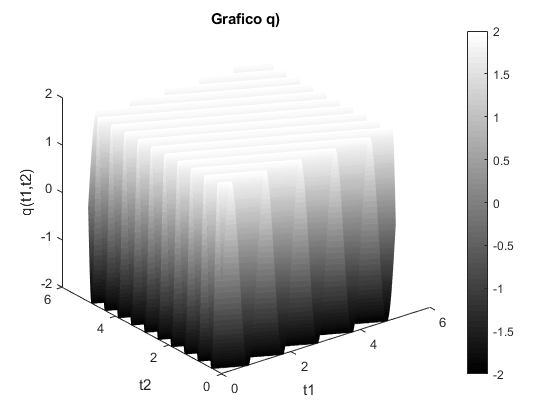

Ta = 1/25;
t = (0:Ta:5);
x1 = (-5:Ta:5);
x2 = (-5:Ta:5);
T = length(t);
r = zeros(length(x1),length(x2));
colorbar;
cmap = colormap;
cmap_gray = [[0:(1/64):1]' [0:(1/64):1]' [0:(1/64):1]']; 
colormap(cmap_gray);

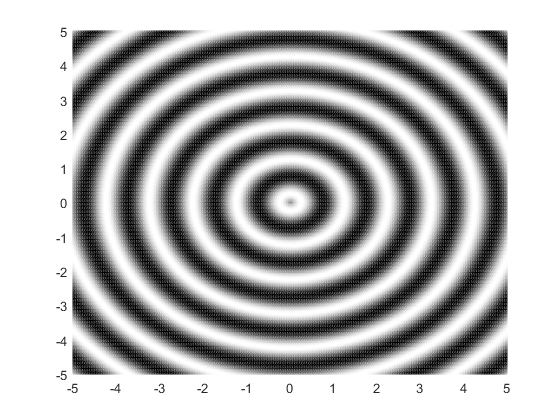

for n = 1:T
    %tic
    for i = 1:length(x1)
        r(i,:) = 2*sin(2*pi*sqrt(x1(i)^2+x2.^2)-2*pi*t(n));
    end
    mesh(x1,x2,r);
    view(2);
    drawnow();
    %pause(Ta-toc);
end